# Track-to-Track Fusion for Automotive Safety Applications

This example shows how to fuse tracks from two vehicles to provide a more comprehensive estimate of the environment than can be seen by each vehicle. The example demonstrates the use of a track-level fuser and the object track data format. In this example, you use the driving scenario and vision detection generator from Automated Driving Toolbox™, the radar data generator from the Radar Toolbox™, and the tracking and track fusion models from Sensor Fusion and Tracking Toolbox™.

## Motivation

Automotive safety applications rely on the fusion of data from different sensor systems mounted on the vehicle. Individual vehicles fuse sensor detections either by using a centralized tracker or by taking a more decentralized approach and fusing tracks produced by individual sensors. In addition to intravehicle data fusion, the fusion of data from multiple vehicles provides added benefits, which include better coverage, situational awareness, and safety [1]. This intervehicle sensor fusion approach takes advantage of the variety of sensors and provides better coverage to each vehicle, because it uses data updated by sensors on other vehicles in the area. Governments and vehicle manufacturers have long recognized the need to share information between vehicles in order to increase automotive safety. For example, V2X protocols and cellular communication links are being developed.

While sensor fusion across multiple vehicles is beneficial, most vehicles are required to meet certain safety requirements even if only internal sensors are available. Therefore, the vehicle is likely to be equipped with a tracker, a track fuser, or both. These tracking algorithms provide situational awareness at the single vehicle level. As a result, the assumption made in this example is that vehicles share situational awareness by broadcasting tracks and performing track-to-track fusion. 

This example demonstrates the benefit of fusing tracks from two vehicles to enhance situational awareness and safety. This example does not simulate the communications systems. Instead, the example assumes that a communications system provides the bandwidth required to transmit tracks between the two vehicles. 

## Track-to-Track Architecture

The following block diagram depicts the main functions in the two vehicles, where: 

- Vehicle 1 has two sensors, each providing detections to a local vehicle tracker. The tracker uses the detections from the local sensors to track objects and outputs these local tracks to the vehicle track fuser. 

- Vehicle 2 has a single sensor, which is a tracking radar. The tracking radar outputs tracks and serves as the local tracker for vehicle 2. The tracks from the tracking radar are inputs to the vehicle track fuser on vehicle 2. 

- The track fuser on each vehicle fuses the local vehicle tracks with the tracks received from the other vehicle's track fuser. After each update, the track fuser on each vehicle broadcasts its fused tracks, which feed into the next update of the track fuser on the other vehicle. 

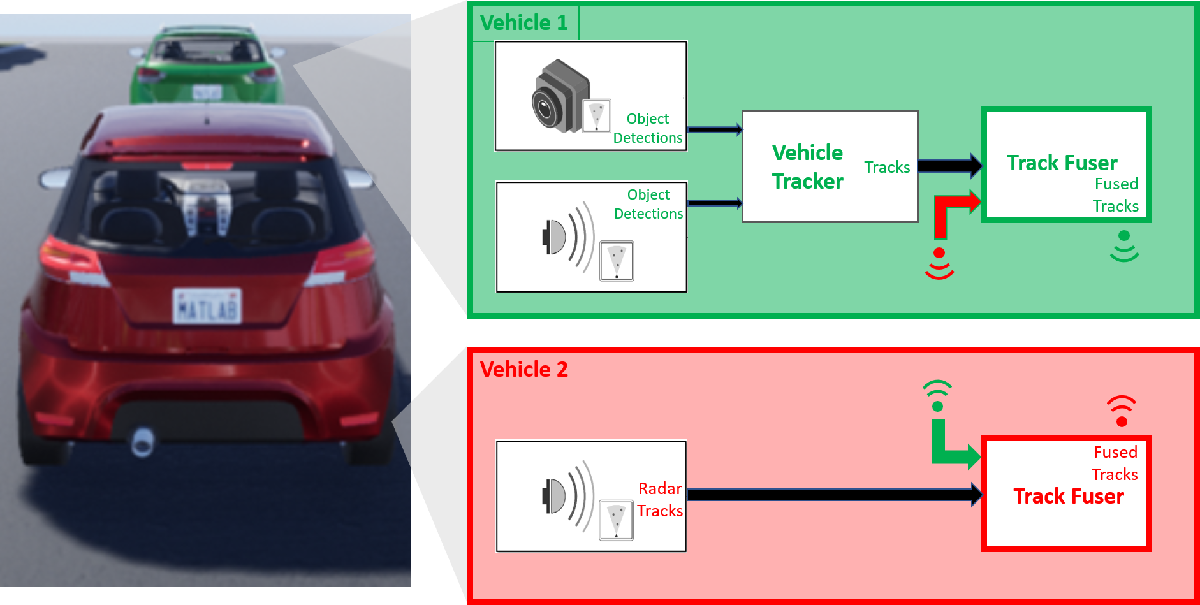

In this example, you use a [trackerJPDA](docid:fusion_ref#sysobj_tracker_jpda) object to define the vehicle 1 tracker. 

% Create the tracker for vehicle 1
v1Tracker = trackerJPDA('TrackerIndex',1, 'DeletionThreshold', [4 4], 'AssignmentThreshold', [100 inf]); % Vehicle 1 tracker
posSelector = [1 0 0 0 0 0; 0 0 1 0 0 0];

In this architecture, the fused tracks from one vehicle update the fused tracks on the other vehicle. These fused tracks are then broadcast back to the first vehicle. To avoid rumor propagation, be careful how tracks from another vehicle update the track fuser. 

Consider the following rumor propagation example: at some update step, vehicle 1 tracks an object using its internal sensors. Vehicle 1 then fuses the object track and transmits it to vehicle 2, which now fuses the track with its own tracks and becomes aware of the object. Up to this point, this is exactly the goal of track-to-track fusion: to enhance the situational awareness of vehicle 2 with information from vehicle 1. Since vehicle 2 now knows about the object, it starts broadcasting the track as well, perhaps for the benefit of another vehicle (not shown in the example). 

However, vehicle 1 now receives track information from vehicle 2 about the object that only vehicle 1 actually tracks. So, the track fuser on vehicle 1 must be aware that the tracks of this object it gets from vehicle 2 do not actually contain any new information updated by an independent source. To make the distinction between tracks that contain new information and tracks that just repeat information, you must define vehicle 2 as an *external source* to the track fuser on vehicle 1. Similarly, vehicle 1 must be defined as an external source to the track fuser on vehicle 2. Furthermore, you need to define only tracks that are updated by a track fuser based on information from an internal source as *self-reported*. By doing so, the track fuser in each vehicle ignores updates from tracks that bounce back and forth between the track fusers without any new information in them. 

The local tracker of each vehicle tracks objects relative to the vehicle reference frame, called the ego frame. The track-to-track fusion is done at the scenario frame, which is the global-level frame. The helper `egoToScenario` function transforms tracks from the ego frame to the scenario frame. Similarly, the function `scenarioToEgo` transforms tracks from the scenario frame to any of the ego frames. Both transformations rely on the `StateParameters` property of the [objectTrack](docid:fusion_ref#class_object_track) objects. When the `trackFuser` object calculates the distance of a central track in the scenario frame to a local track in any frame, it uses the `StateParameters` of the local track to perform the coordinate transformation.

To achieve the previously described `trackFuser` definitions, define the following sources as a [fuserSourceConfiguration](docid:fusion_ref#class_fuser_source_configuration) object.

% Define sources for each vehicle
v1TrackerConfiguration = fuserSourceConfiguration('SourceIndex',1,'IsInternalSource',true, ...   % v1Tracker is internal to v1Fuser
    "CentralToLocalTransformFcn", @scenarioToEgo, 'LocalToCentralTransformFcn', @egoToScenario); % Coordinate transformation
v2FuserConfiguration = fuserSourceConfiguration('SourceIndex',4,'IsInternalSource',false);       % v2Fuser is external to v2Fuser
v1Sources = {v1TrackerConfiguration; v2FuserConfiguration};
v2TrackerConfiguration = fuserSourceConfiguration('SourceIndex',2,'IsInternalSource',true, ...   % v2Tracker is internal to v2Fuser
    "CentralToLocalTransformFcn", @scenarioToEgo, 'LocalToCentralTransformFcn', @egoToScenario); % Coordinate transformation
v1FuserConfiguration = fuserSourceConfiguration('SourceIndex',3,'IsInternalSource',false);       % v1Fuser is external to v2Fuser
v2Sources = {v2TrackerConfiguration; v1FuserConfiguration};

You can now define each vehicle track fuser as a [trackFuser](docid:fusion_ref#sysobj_track_fuser) object.

stateParams = struct('Frame','Rectangular','Position',[0 0 0],'Velocity',[0 0 0]);
v1Fuser = trackFuser('FuserIndex',3,...
    'AssignmentThreshold', [100 inf], ...
    'MaxNumSources',2,'SourceConfigurations',v1Sources,...
    'StateFusion','Intersection','DeletionThreshold',[3 3],...
    'StateParameters',stateParams);
v2Fuser = trackFuser('FuserIndex',4,...
    'AssignmentThreshold', [100 inf], ...
    'MaxNumSources',2,'SourceConfigurations',v2Sources,'StateFusion',...
    'Intersection','DeletionThreshold',[3 3],...
    'StateParameters',stateParams);

% Initialize the following variables
fusedTracks1 = objectTrack.empty(0,1);
fusedTracks2 = objectTrack.empty(0,1);
wasFuser1Updated = false;
wasFuser2Updated = false;

## Define Scenario

The following scenario shows two vehicles driving down a street. Vehicle 1 is the lead vehicle and is equipped with two forward-looking sensors: a short-range radar sensor and a vision sensor. Vehicle 2, driving 10 meters behind vehicle 1, is equipped with a long-range radar. The right side of the street contains parked vehicles. A pedestrian stands between the vehicles. This pedestrian is shown as a dot at about X = 60 meters. 

Due to the short distance between vehicle 2 and vehicle 1, most of the vehicle 2 radar sensor coverage is occluded by vehicle 1. As a result, most of the tracks that the track fuser on vehicle 2 maintains are first initialized by tracks broadcast from vehicle 1.

% Create the drivingScenario object and the two vehicles
[scenario, vehicle1, vehicle2] = createDrivingScenario;

% Create all the sensors
[sensors, numSensors, attachedVehicle] = createSensors(scenario);

% Create display
[f,plotters] = createV2VDisplay(scenario, sensors, attachedVehicle);

The following chase plot is seen from the point of view of the second vehicle. An arrow indicates the position of the pedestrian that is almost entirely occluded by the parked vehicles and the first vehicle.

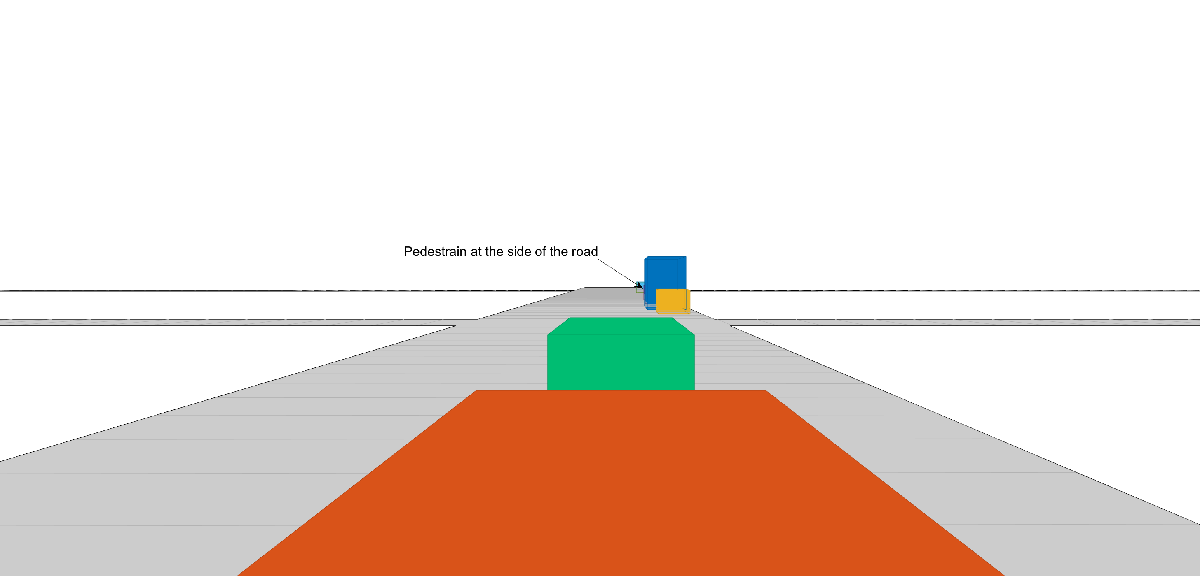

% Define each vehicle as a combination of an actor, sensors, a tracker, and plotters
v1=struct('Actor',{vehicle1},'Sensors',{sensors(attachedVehicle==1)},'Tracker',{v1Tracker},'DetPlotter',{plotters.veh1DetPlotter},'TrkPlotter',{plotters.veh1TrkPlotter});
v2=struct('Actor',{vehicle2},'Sensors',{sensors(attachedVehicle==2)},'Tracker',{{}},'DetPlotter',{{}},'TrkPlotter',{plotters.veh2TrkPlotter}); % No detections or tracker on Vehicle 2

## Run Simulation

The following code runs the simulation.

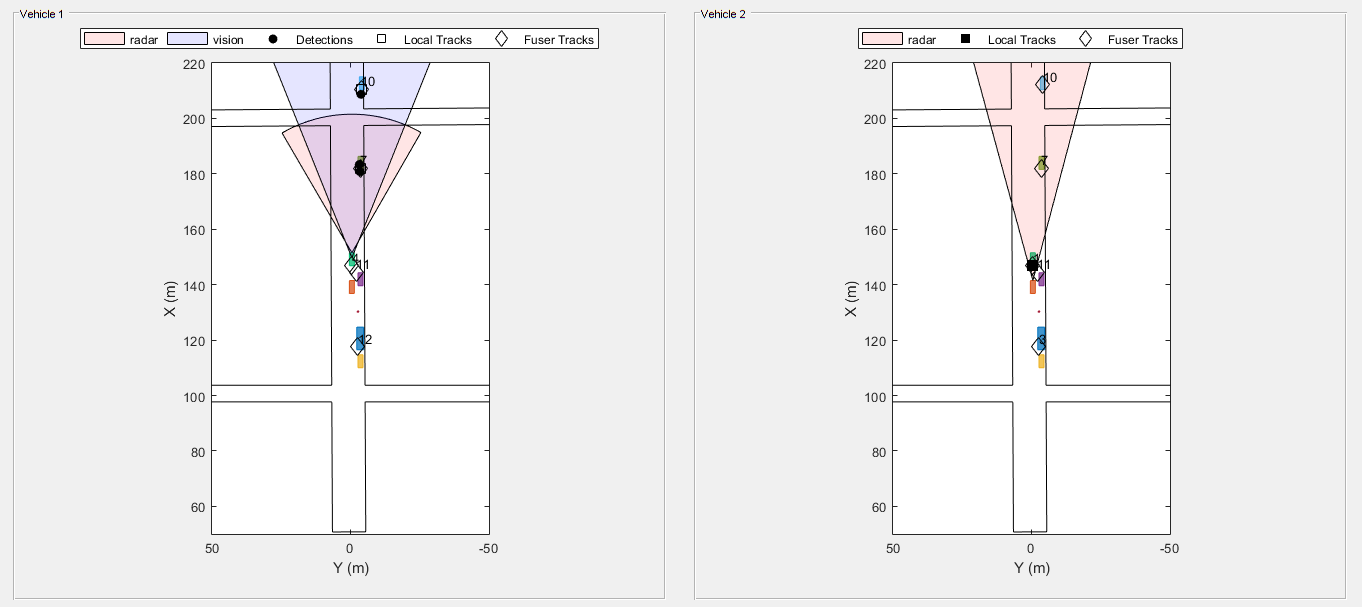

running = true;

% For repeatable results, set the random number seed
s = rng;
rng(2019)
snaptimes = [0.5, 2.8, 4.4, 6.3, inf];
snaps = cell(numel(snaptimes,1));
i = 1;
f.Visible = 'on';
while running && ishghandle(f)
    time  = scenario.SimulationTime;

    % Detect and track at the vehicle level
    [tracks1,wasTracker1Updated] = detectAndTrack(v1,time,posSelector);
    [tracks2,wasTracker2Updated] = detectAndTrack(v2,time,posSelector);

    % Keep the tracks from the previous fuser update
    oldFusedTracks1 = fusedTracks1;
    oldFusedTracks2 = fusedTracks2;

    % Update the fusers
    if wasTracker1Updated || wasFuser2Updated
        tracksToFuse1 = [tracks1;oldFusedTracks2];
        if isLocked(v1Fuser) || ~isempty(tracksToFuse1)
            [fusedTracks1,~,~,info1] = v1Fuser(tracksToFuse1,time);
            wasFuser1Updated = true;
            pos = getTrackPositions(fusedTracks1,posSelector);
            ids = string([fusedTracks1.TrackID]');
            plotTrack(plotters.veh1FusePlotter,pos,ids);
        else
            wasFuser1Updated = false;
            fusedTracks1 = objectTrack.empty(0,1);
        end
    else
        wasFuser1Updated = false;
        fusedTracks1 = objectTrack.empty(0,1);
    end
    if wasTracker2Updated || wasFuser1Updated
        tracksToFuse2 = [tracks2;oldFusedTracks1];
        if isLocked(v2Fuser) || ~isempty(tracksToFuse2)
            [fusedTracks2,~,~,info2] = v2Fuser(tracksToFuse2,time);
            wasFuser2Updated = true;
            pos = getTrackPositions(fusedTracks2,posSelector);
            ids = string([fusedTracks2.TrackID]');
            plotTrack(plotters.veh2FusePlotter,pos,ids);
        else
            wasFuser2Updated = false;
            fusedTracks2 = objectTrack.empty(0,1);
        end
    else
        wasFuser2Updated = false;
        fusedTracks2 = objectTrack.empty(0,1);
    end

    % Update the display
    updateV2VDisplay(plotters, scenario, sensors, attachedVehicle)

    % Advance the scenario one time step and exit the loop if the scenario is complete
    running = advance(scenario);

    % Capture an image of the frame at specified times
    if time >= snaptimes(i)
        snaps{i} = takesnap(f);
        i = i + 1;
    end
end

The figure shows the scene and tracking results at the end of the scenario. Subsequent sections of this example analyze the tracking results at key times.

### Analyze Tracking at Beginning of Simulation

When the simulation begins, vehicle 1 detects the vehicles parked on the right side of the street. Then, vehicle 1 tracker confirms the tracks associated with the parked vehicles. At this time, the only object detected and tracked by vehicle 2 tracker is vehicle 1, which is immediately in front of it. Once the vehicle 1 track fuser confirms the tracks, it broadcasts them, and the vehicle 2 track fuser fuses them. As a result, vehicle 2 becomes aware of the parked vehicles before it can detect them on its own.

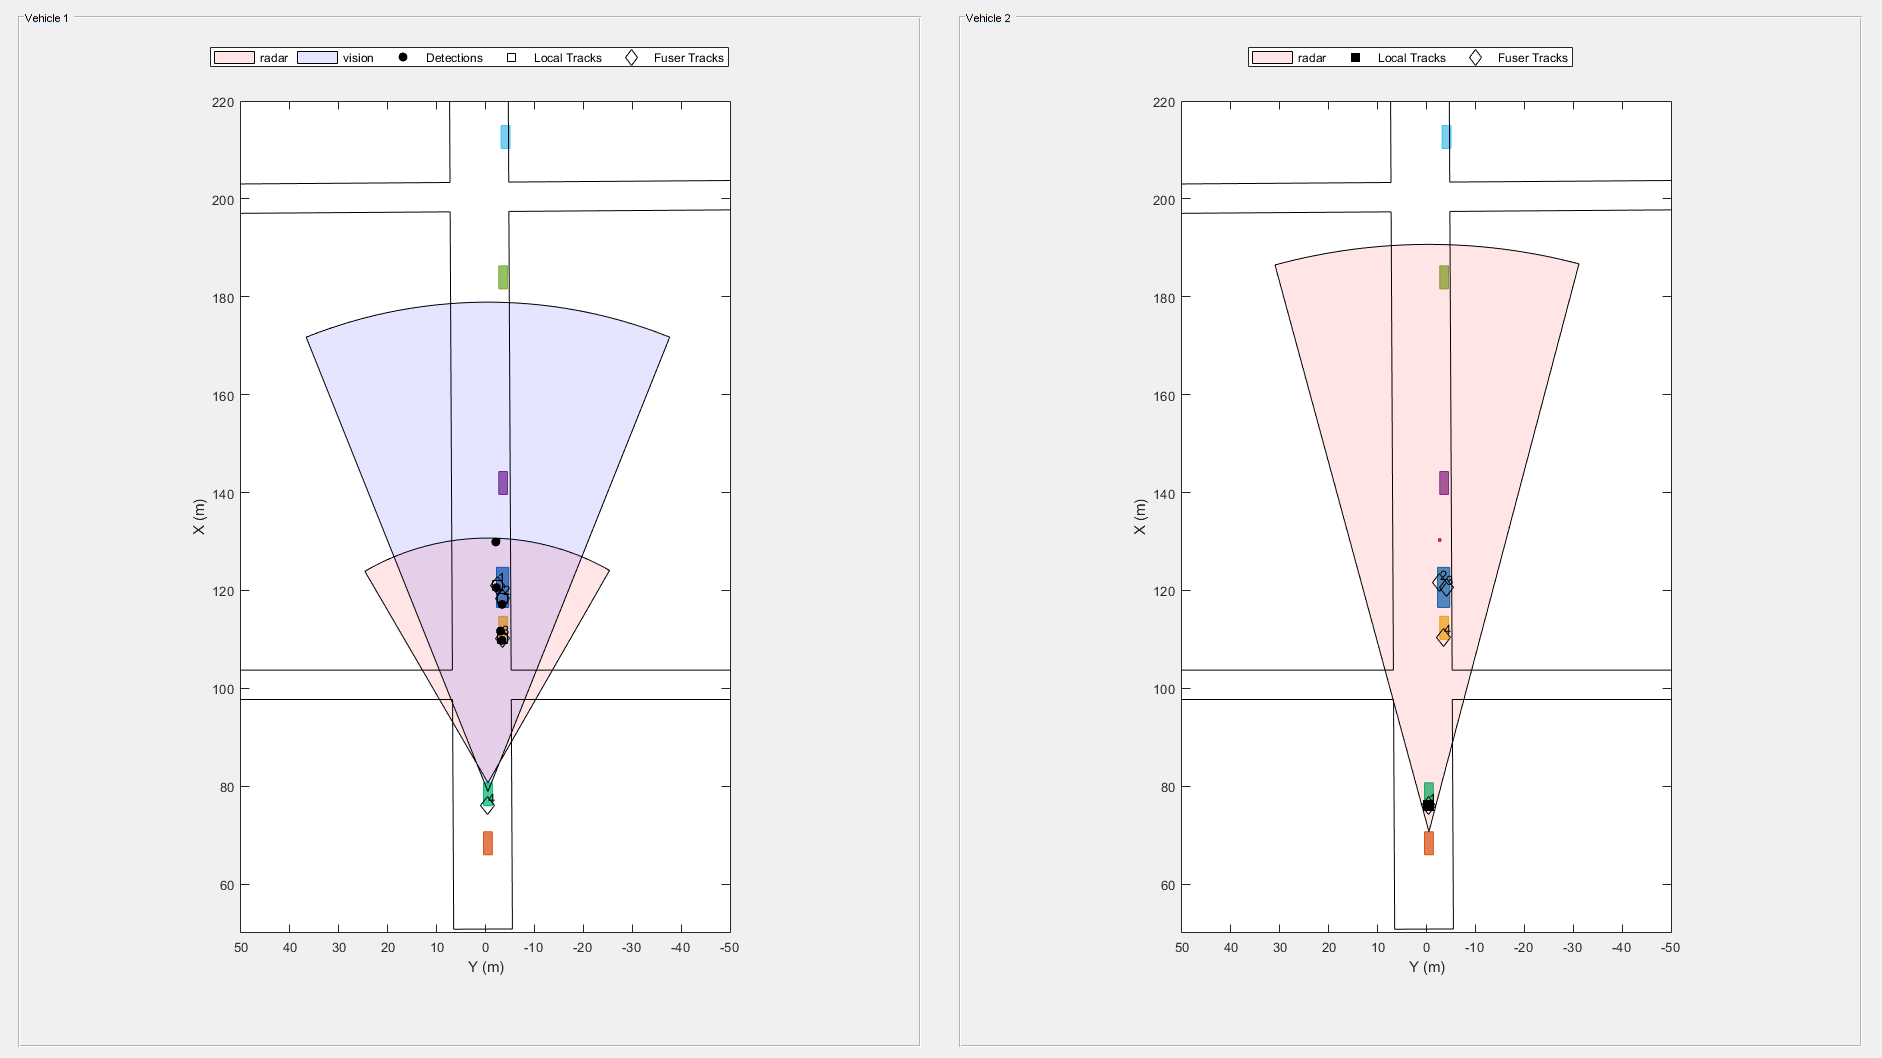

showsnap(snaps,1)

### Analyze Tracking of Pedestrian at Side of Street

As the simulation continues, vehicle 2 is able to detect and track the vehicles parked at the side as well and fuses them with the tracks coming from vehicle 1. Vehicle 2 is able to detect and track the pedestrian about 4 seconds into the simulation, and vehicle 2 fuses the track associated with the pedestrian around 4.4 seconds into the simulation (see snapshot 2). However, it takes vehicle 2 about two seconds before it can detect and track the pedestrian by its own sensors (see snapshot 3). Detecting a pedestrian in the street two seconds earlier can markedly improve safety. 

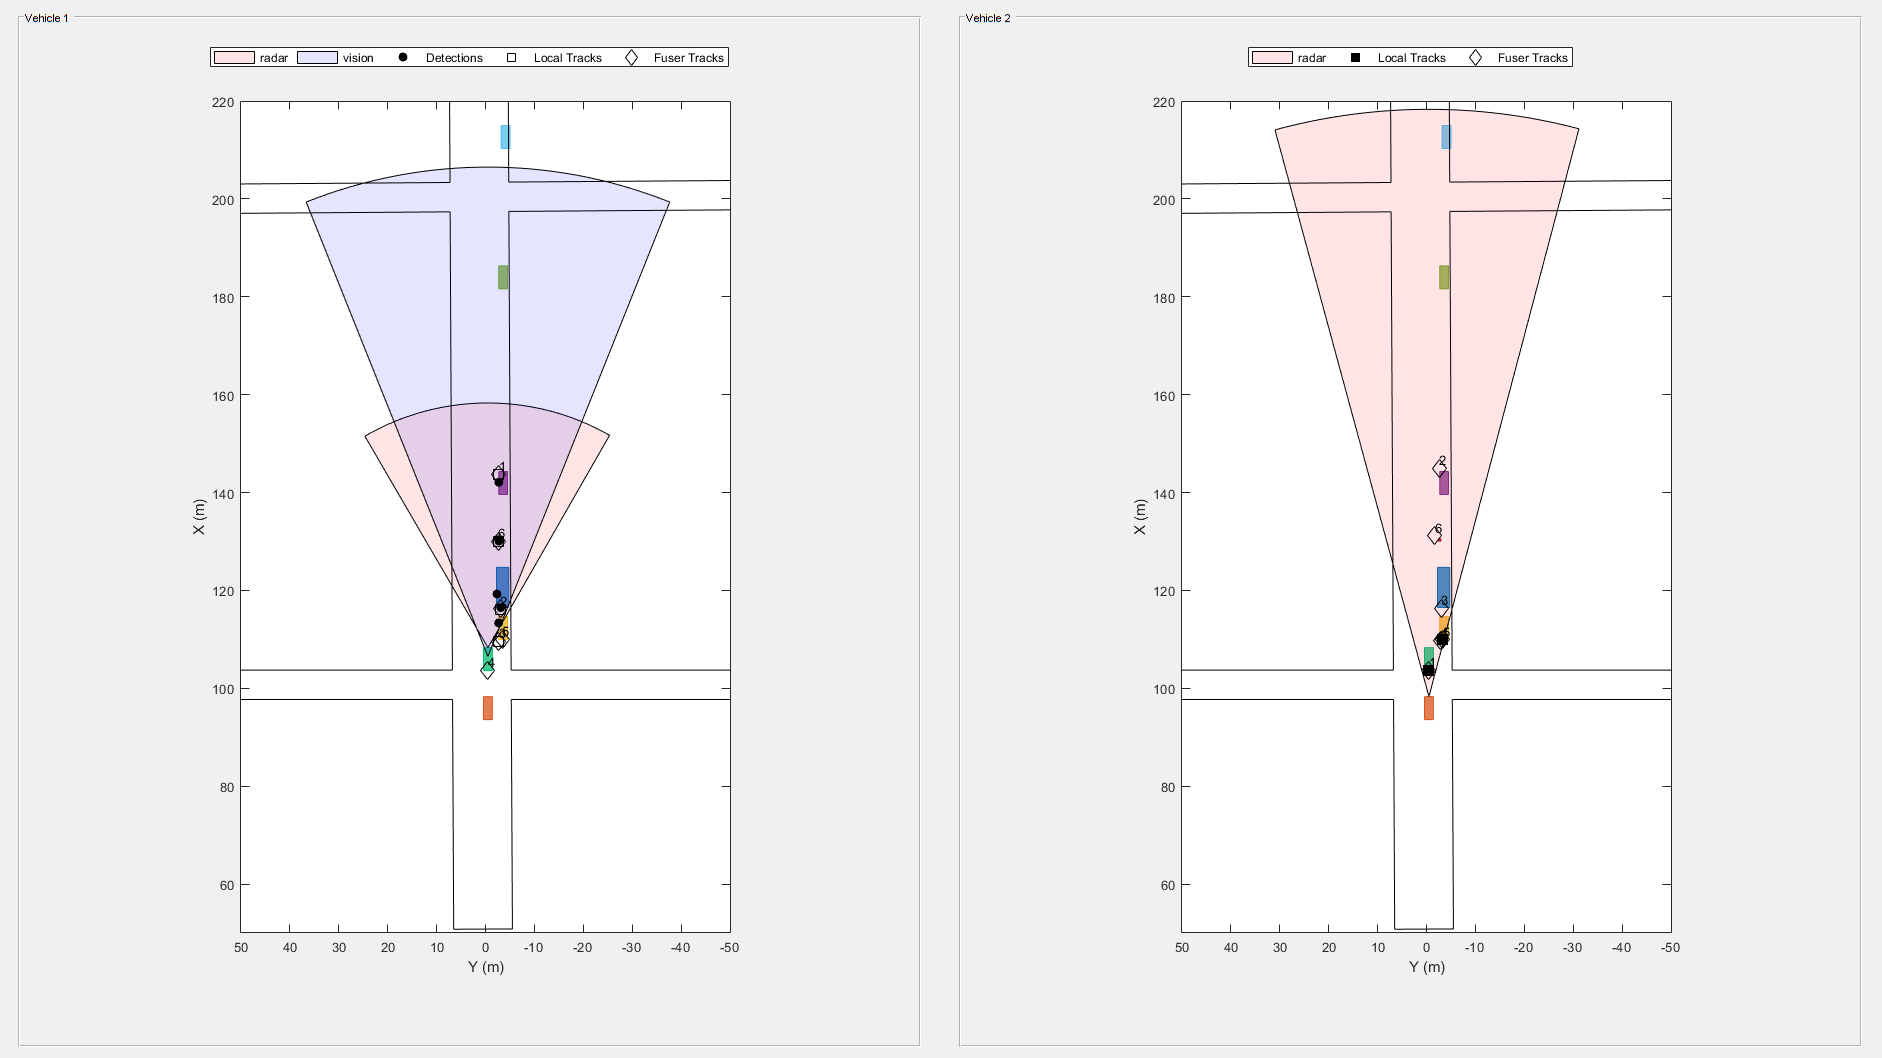

showsnap(snaps,2)

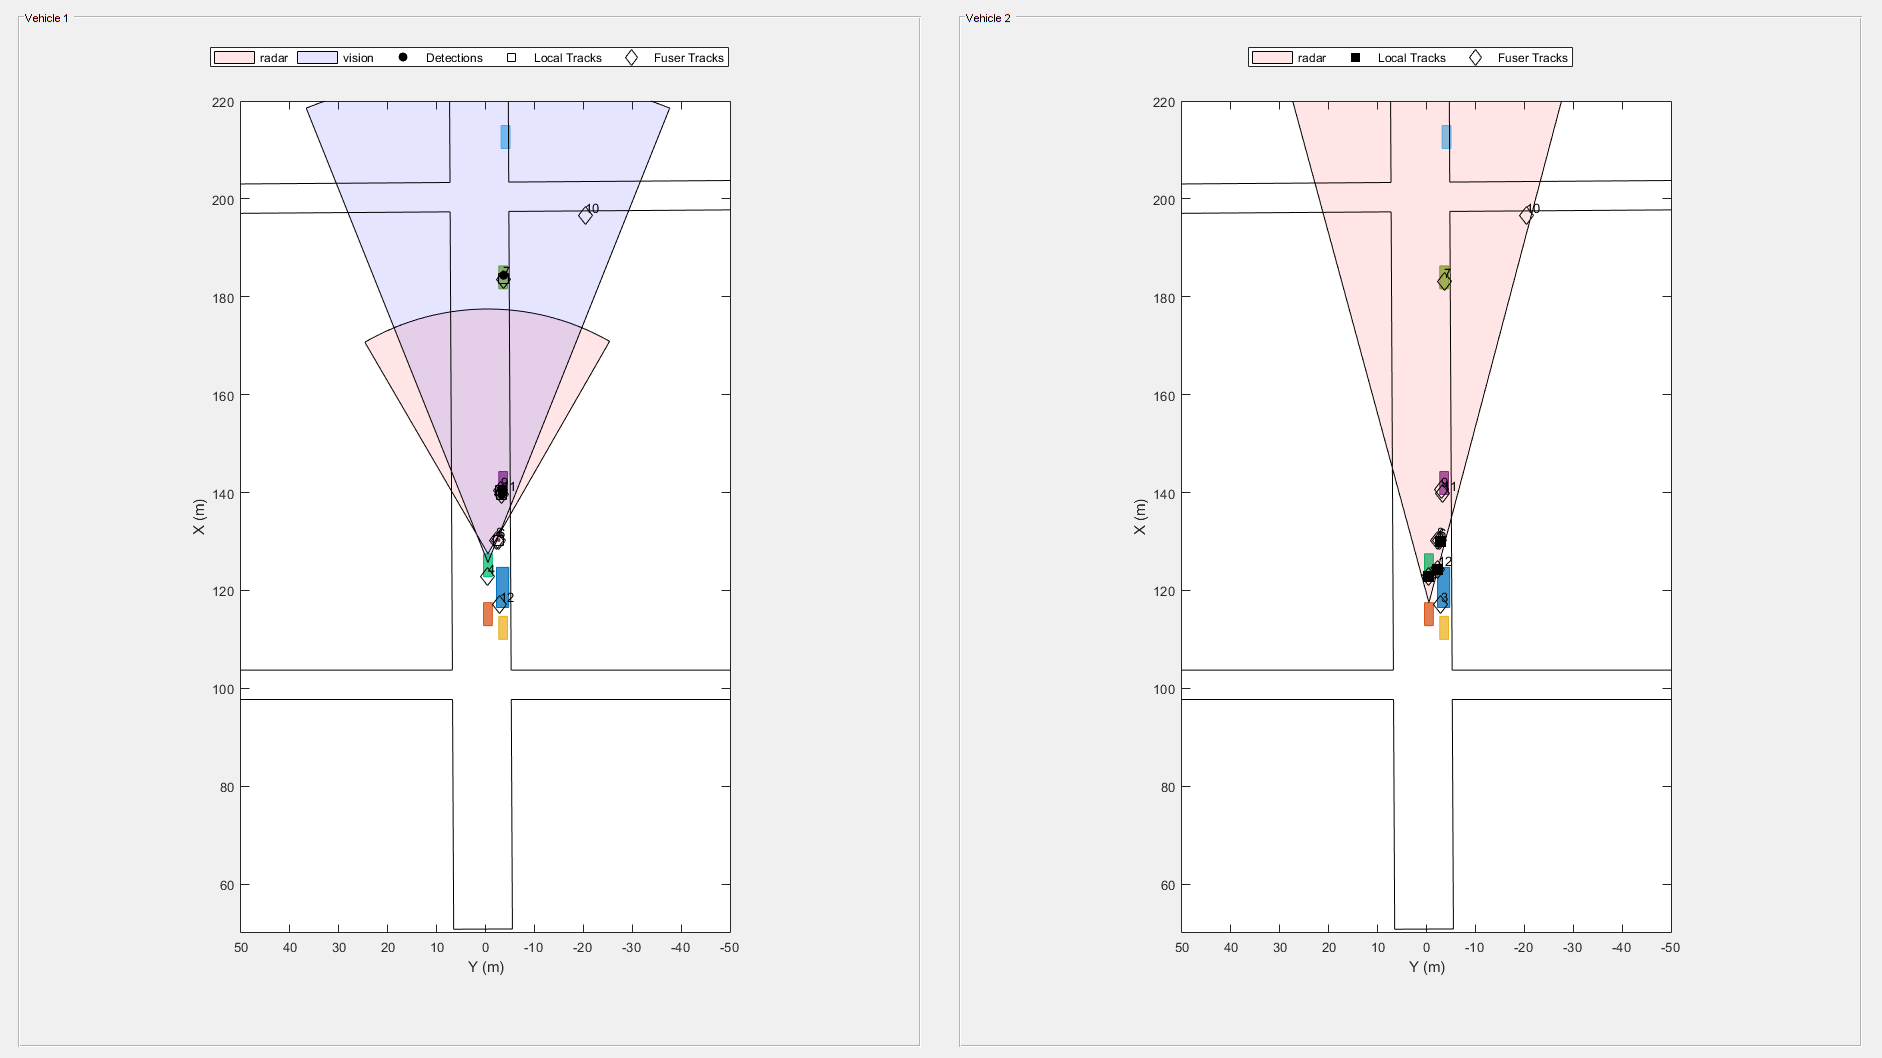

showsnap(snaps,3)

### Avoiding Rumor Propagation

When the two vehicles communicate tracks to each other, there is a risk that they will continue communicating information about objects that they do not detect anymore just by repeating what the other vehicle communicated. This situation is called rumor propagation. 

As the vehicles pass the objects, and these objects go out of their field of view, the fused tracks associated with these objects are dropped by both trackers (see snapshot 4). Dropping the tracks demonstrates that the fused tracks broadcast back and forth between the two vehicles are not used to propagate rumors. 

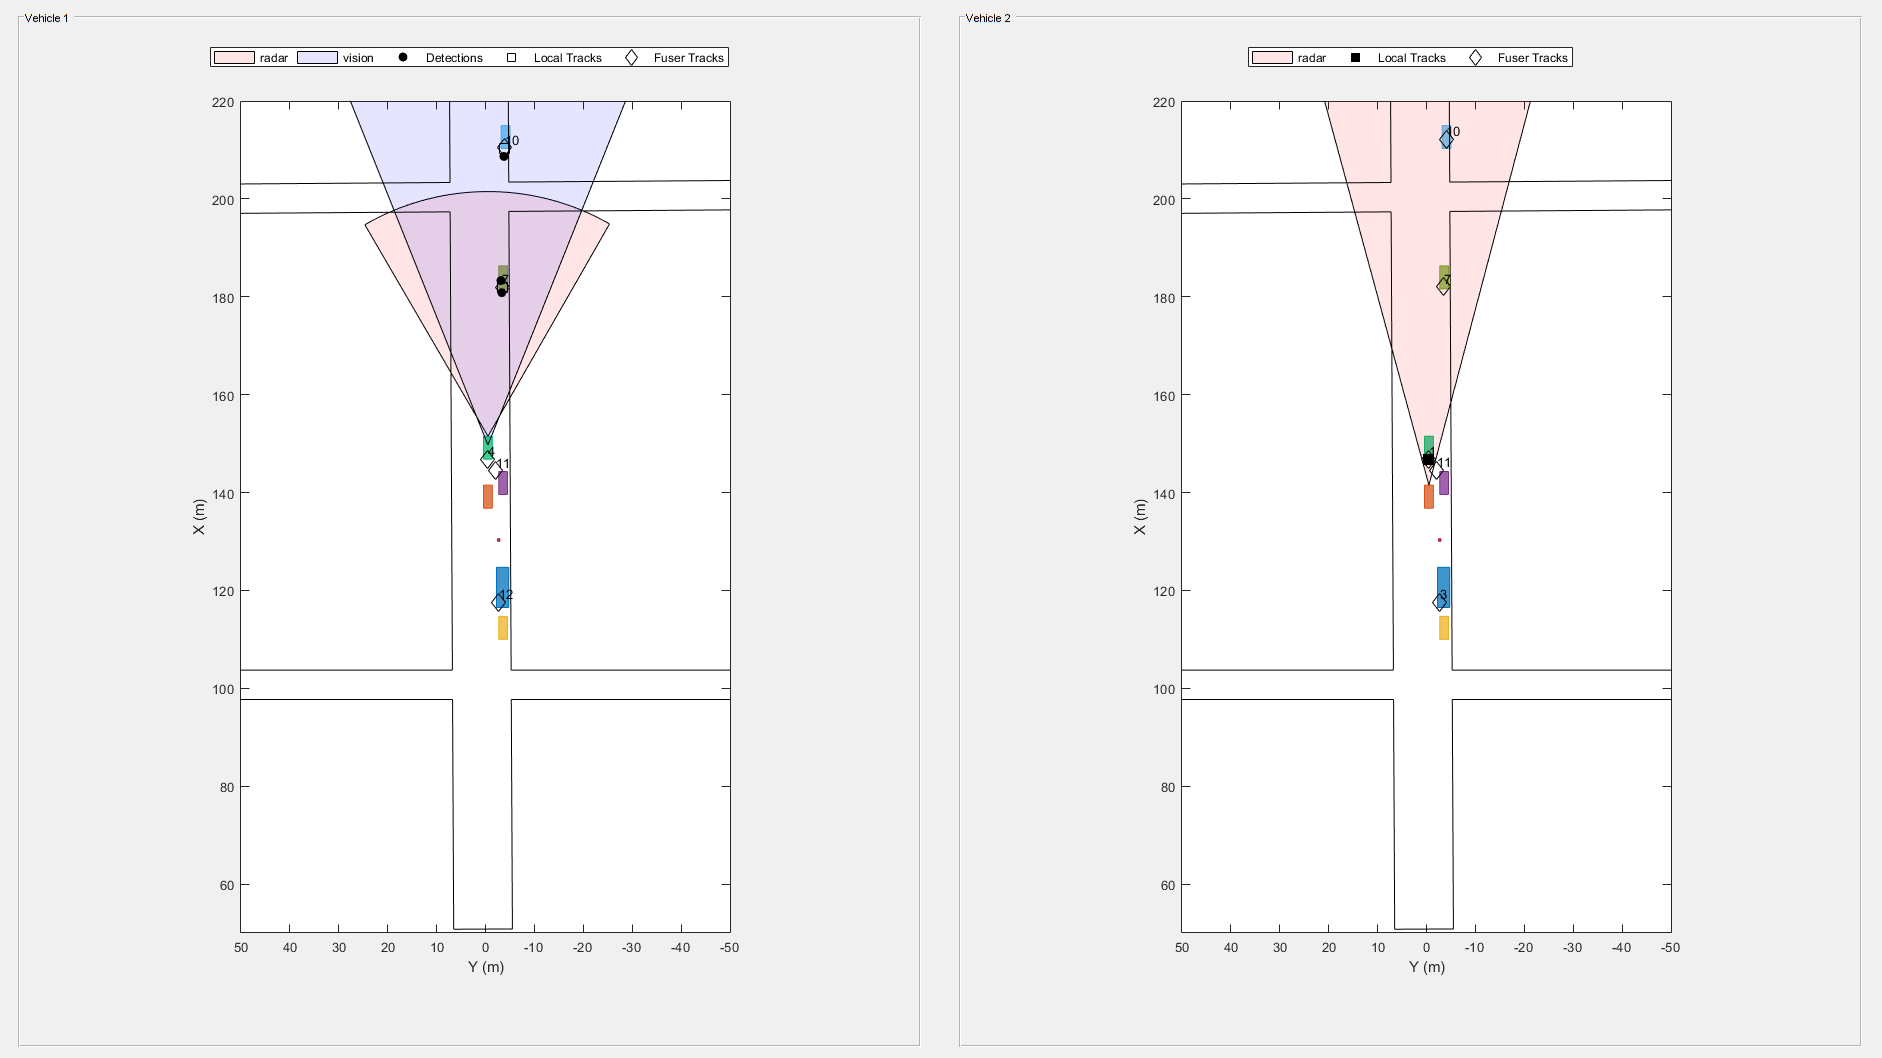

showsnap(snaps,4)


% Restart the driving scenario to return the actors to their initial positions
restart(scenario);

% Release all the sensor objects so they can be used again
for sensorIndex = 1:numSensors
    release(sensors{sensorIndex});
end

% Return the random seed to its previous value
rng(s)

## Summary

In this example, you saw how track-to-track fusion can enhance the situational awareness and increase the safety in automotive applications. You saw how to set up a `trackFuser` to perform track-to-track fusion and how to define sources as either internal or external by using the `fuserSourceConfiguration` object. By doing so, you avoid rumor propagation and keep only the fused tracks that are really observed by each vehicle to be maintained.

## References

[1] Duraisamy, B., T. Schwarz, and C. Wohler. “Track Level Fusion Algorithms for Automotive Safety Applications.” In *2013 International Conference on Signal Processing , Image Processing & Pattern Recognition*, 179–84, 2013. [https://doi.org/10.1109/ICSIPR.2013.6497983](https://doi.org/10.1109/ICSIPR.2013.6497983).

## Supporting Functions

### `createDrivingScenario`

Create a driving scenario defined in the **Driving Scenario Designer** app.

function [scenario, egoVehicle, secondVehicle] = createDrivingScenario
% Construct a drivingScenario object
scenario = drivingScenario('SampleTime', 0.1);

% Add all road segments
roadCenters = [50.8 0.5 0; 253.4 1.5 0];
roadWidth = 12;
road(scenario, roadCenters, roadWidth);

roadCenters = [100.7 -100.6 0; 100.7 103.7 0];
road(scenario, roadCenters);

roadCenters = [201.1 -99.2 0; 199.7 99.5 0];
road(scenario, roadCenters);

% Add the ego vehicle
egoVehicle = vehicle(scenario, 'ClassID', 1, 'Position', [65.1 -0.9 0], 'PlotColor', [0 0.7410 0.4470]);
waypoints = [71 -0.5 0; 148.7 -0.5 0];
speed = 12;
trajectory(egoVehicle, waypoints, speed);

% Add the second vehicle
secondVehicle = vehicle(scenario, 'ClassID', 1, 'Position', [55.1 -0.9 0]);
waypoints = [61 -0.5 0; 138.7 -0.5 0];
speed = 12;
trajectory(secondVehicle, waypoints, speed);

% Add the parked cars
vehicle(scenario, 'ClassID', 1, 'Position', [111.0 -3.6 0]);
vehicle(scenario, 'ClassID', 1, 'Position', [140.6 -3.6 0]);
vehicle(scenario, 'ClassID', 1, 'Position', [182.6 -3.6 0]);
vehicle(scenario, 'ClassID', 1, 'Position', [211.3 -4.1 0]);

% Add pedestrian
actor(scenario, 'ClassID', 4, 'Length', 0.5, 'Width', 0.5, ...
    'Height', 1.7, 'Position', [130.3 -2.7 0], 'RCSPattern', [-8 -8;-8 -8]);

% Add parked truck
vehicle(scenario, 'ClassID', 2, 'Length', 8.2, 'Width', 2.5, ...
    'Height', 3.5, 'Position', [117.5 -3.5 0]);
end

### `createSensors`

Create the sensors used in the scenario and list their attachments to vehicles.

function [sensors, numSensors, attachedVehicle] = createSensors(scenario)
% createSensors Returns all sensor objects to generate detections
% Units used in createSensors and createDrivingScenario
% Distance/Position - meters
% Speed             - meters/second
% Angles            - degrees
% RCS Pattern       - dBsm

% Assign into each sensor the physical and radar profiles for all actors
profiles = actorProfiles(scenario);

% Vehicle 1 radar reports clustered detections
sensors{1} = radarDataGenerator('No scanning', 'SensorIndex', 1, 'UpdateRate', 10, ...
    'MountingLocation', [3.7 0 0.2], 'RangeLimits', [0 50], 'FieldOfView', [60 5], ...
    'RangeResolution', 2.5, 'AzimuthResolution', 4, ...
    'Profiles', profiles, 'HasOcclusion', true, 'HasFalseAlarms', false, ...
    'TargetReportFormat', 'Clustered detections');

% Vehicle 2 radar reports tracks
sensors{2} = radarDataGenerator('No scanning', 'SensorIndex', 2, 'UpdateRate', 10, ...
    'MountingLocation', [3.7 0 0.2], 'RangeLimits', [0 120], 'FieldOfView', [30 5], ...
    'RangeResolution', 2.5, 'AzimuthResolution', 4, ...
    'Profiles', profiles, 'HasOcclusion', true, 'HasFalseAlarms', false, ...
    'TargetReportFormat', 'Tracks', 'DeletionThreshold', [3 3]);

% Vehicle 1 vision sensor reports detections
sensors{3} = visionDetectionGenerator('SensorIndex', 3, ...
    'MaxRange', 100, 'SensorLocation', [1.9 0], 'DetectorOutput', 'Objects only', ...
    'ActorProfiles', profiles);
attachedVehicle = [1;2;1];
numSensors = numel(sensors);
end

### `scenarioToEgo`

Perform coordinate transformation from scenario to ego coordinates.

`trackInScenario` has `StateParameters` defined to transform it from scenario coordinates to ego coordinates.

The state uses the constant velocity model [x;vx;y;vy;z;vz].

function trackInEgo = scenarioToEgo(trackInScenario)
egoPosInScenario = trackInScenario.StateParameters.OriginPosition;
egoVelInScenario = trackInScenario.StateParameters.OriginVelocity;
stateInScenario = trackInScenario.State;
stateShift = [egoPosInScenario(1);egoVelInScenario(1);egoPosInScenario(2);egoVelInScenario(2);egoPosInScenario(3);egoVelInScenario(3)];
stateInEgo = stateInScenario - stateShift;
trackInEgo = objectTrack('UpdateTime',trackInScenario.UpdateTime,'State',stateInEgo,'StateCovariance',trackInScenario.StateCovariance,'StateParameters',trackInScenario.StateParameters);
end

### `egoToScenario`

Perform coordinate transformation from ego to scenario coordinates.

`trackInEgo` has `StateParameters` defined to transform it from ego coordinates to scenario coordinates.

The state uses the constant velocity model [x;vx;y;vy;z;vz].

function trackInScenario = egoToScenario(trackInEgo)
egoPosInScenario = trackInEgo.StateParameters.OriginPosition;
egoVelInScenario = trackInEgo.StateParameters.OriginVelocity;
stateInScenario = trackInEgo.State;
stateShift = [egoPosInScenario(1);egoVelInScenario(1);egoPosInScenario(2);egoVelInScenario(2);egoPosInScenario(3);egoVelInScenario(3)];
stateInEgo = stateInScenario + stateShift;
trackInScenario = objectTrack('UpdateTime',trackInEgo.UpdateTime,'State',stateInEgo,'StateCovariance',trackInEgo.StateCovariance,'StateParameters',trackInEgo.StateParameters);
end

### `detectAndTrack`

This function is used for collecting all the detections from the sensors in one vehicle and updating the tracker with them.

The agent is a structure that contains the actor information and the sensors, tracker, and plotter to plot detections and vehicle tracks.

function [tracks,wasTrackerUpdated] = detectAndTrack(agent,time,posSelector)
% Create detections from the vehicle
poses = targetPoses(agent.Actor);
[detections,isValid] = vehicleDetections(agent.Actor.Position,agent.Sensors,poses,time,agent.DetPlotter);

% Update the tracker to get tracks from sensors that reported detections
if isValid
    agent.Tracker.StateParameters = struct(...
        'Frame','Rectangular', ...
        'OriginPosition', agent.Actor.Position, ...
        'OriginVelocity', agent.Actor.Velocity);
    tracks = agent.Tracker(detections,time);
    tracksInScenario = tracks;
    for i = 1:numel(tracks)
        tracksInScenario(i) = egoToScenario(tracks(i));
    end
    pos = getTrackPositions(tracksInScenario,posSelector);
    plotTrack(agent.TrkPlotter,pos)
    wasTrackerUpdated = true;
else
    tracks = objectTrack.empty(0,1);
    wasTrackerUpdated = false;
end

% Get additional tracks from tracking sensors
[sensorTracks,wasSensorTrackerUpdated] = vehicleTracks(agent.Actor,agent.Sensors,poses,time,agent.TrkPlotter);
tracks = vertcat(tracks,sensorTracks);
wasTrackerUpdated = wasTrackerUpdated || wasSensorTrackerUpdated;
end

### `vehicleDetections`

Collect the detections from all the sensors attached to this vehicle that return detections.

function [objectDetections,isValid] = vehicleDetections(position, sensors, poses, time, plotter)
numSensors = numel(sensors);
objectDetections = {};
isValidTime = false(1, numSensors);

% Generate detections for each sensor
for sensorIndex = 1:numSensors
    sensor = sensors{sensorIndex};
    if isa(sensor, 'visionDetectionGenerator') || ~strcmpi(sensor.TargetReportFormat,'Tracks')
        [objectDets, ~, sensorConfig] = sensor(poses, time);
        if islogical(sensorConfig)
            isValidTime(sensorIndex) = sensorConfig;
        else
            isValidTime(sensorIndex) = sensorConfig.IsValidTime;
        end
        objectDets = cellfun(@(d) setAtt(d), objectDets, 'UniformOutput', false);
        numObjects = numel(objectDets);
        objectDetections = [objectDetections; objectDets(1:numObjects)]; %#ok<AGROW>
    end
end
isValid = any(isValidTime);

% Plot detections
if numel(objectDetections)>0
    detPos = cellfun(@(d)d.Measurement(1:2), objectDetections, 'UniformOutput', false);
    detPos = cell2mat(detPos')' + position(1:2);
    plotDetection(plotter, detPos);
end
end

function d = setAtt(d)
% Set the attributes to be a structure
d.ObjectAttributes = struct;
% Keep only the position measurement and remove velocity
if numel(d.Measurement)==6
    d.Measurement = d.Measurement(1:3);
    d.MeasurementNoise = d.MeasurementNoise(1:3,1:3);
    d.MeasurementParameters{1}.HasVelocity = false;
end
end

### `vehicleTracks`

Collect all the tracks from sensors that report tracks on the vehicle.

function [tracks,wasTrackerUpdated] = vehicleTracks(actor, sensors, poses, time, plotter)
% Create detections from the vehicle
numSensors = numel(sensors);
tracks = objectTrack.empty;
isValidTime = false(1, numSensors);

% Generate detections for each sensor
for sensorIndex = 1:numSensors
    sensor = sensors{sensorIndex};
    if isa(sensor, 'radarDataGenerator') && strcmpi(sensor.TargetReportFormat,'Tracks')
        [sensorTracks, ~, sensorConfig] = sensor(poses, time);
        if islogical(sensorConfig)
            isValidTime(sensorIndex) = sensorConfig;
        else
            isValidTime(sensorIndex) = sensorConfig.IsValidTime;
        end
        numObjects = numel(sensorTracks);
        tracks = [tracks; sensorTracks(1:numObjects)]; %#ok<AGROW>
    end
end
wasTrackerUpdated = any(isValidTime);

if ~wasTrackerUpdated % No vehicle tracking sensor udpated
    return
end

% Add vehicle position and velocity to track state parameters
for i = 1:numel(tracks)
    tracks(i).StateParameters.OriginPosition = tracks(i).StateParameters.OriginPosition + actor.Position';
    tracks(i).StateParameters.OriginVelocity = tracks(i).StateParameters.OriginVelocity + actor.Velocity';
end

% Plot tracks
if numel(tracks)>0
    trPos = arrayfun(@(t)t.State([1,3]), tracks, 'UniformOutput', false);
    trPos = cell2mat(trPos')' + actor.Position(1:2);
    plotTrack(plotter, trPos);
end
end

*Copyright 2019-2020 The MathWorks, Inc.*